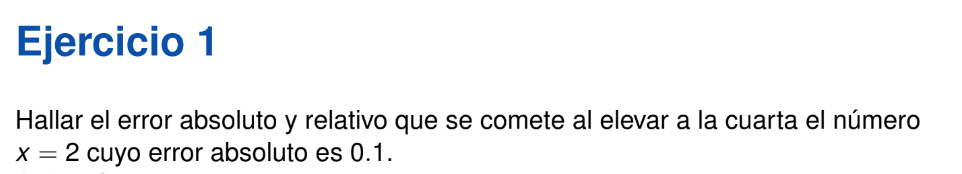

error = (2 + 0.1)^4;
exacto = 2^4;

errorAbsoluto = abs(exacto - error)

errorAbsoluto = 3.4481

errorRelativo = abs(exacto - error) / abs(exacto)

errorRelativo = 0.2155

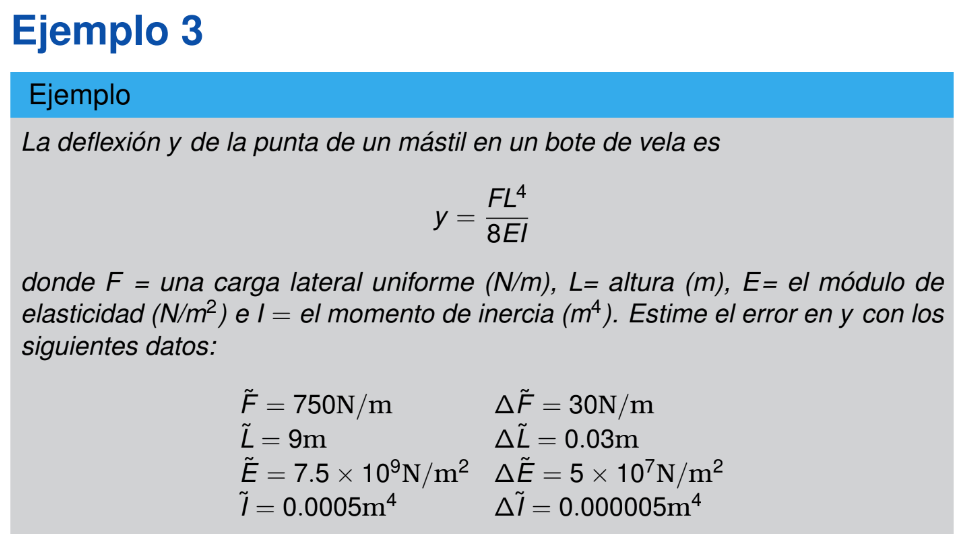

syms y F L E I 

y = @(F,L,E,I) (F*L^4) / (8*E*I)

y = function_handle with value:
    @(F,L,E,I)(F*L^4)/(8*E*I)


F_val = 750;
L_val = 9;
E_val = 7.5 * 10^9;
I_val = 0.0005;

eaF = 30;
eaL =  0.03;
eaE = 5 * 10^7;
eaI = 0.000005;

dy_dF = matlabFunction(diff(y,F));
dy_dL = matlabFunction(diff(y,L));
dy_dE = matlabFunction(diff(y,E));
dy_dI = matlabFunction(diff(y,I));

eay = abs(dy_dF(E_val,I_val,L_val)) * eaF + abs(dy_dL(E_val,F_val,I_val,L_val)) * eaL + abs(dy_dE(E_val,F_val,I_val,L_val)) *eaE + abs(dy_dI(E_val,F_val,I_val,L_val)) *eaI

eay = 0.0115

valorExacto = y(F_val,L_val,E_val,I_val)

valorExacto = 0.1640

maxValor = valorExacto + eay

maxValor = 0.1755

minValor = valorExacto - eay

minValor = 0.1525

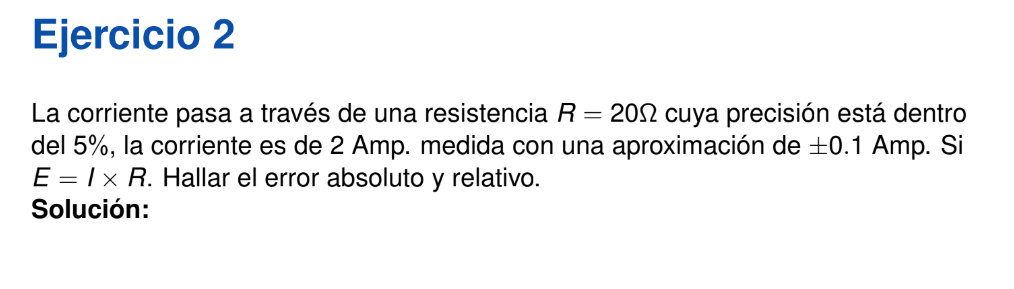

syms R I

E = @(R,I) I * R

E = function_handle with value:
    @(R,I)I*R



R_val = 20;
I_val = 2;
eaR = 5/100 * 20;
eaI = 0.1;

dE_dR = matlabFunction(diff(E,R))

dE_dR = function_handle with value:
    @(I)I


dE_dI = matlabFunction(diff(E,I))

dE_dI = function_handle with value:
    @(R)R



eaE = abs(dE_dR(I_val)) * eaR + abs(dE_dI(R_val))* eaI

eaE = 4

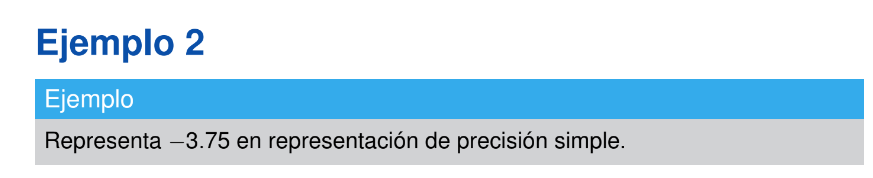

% Función para convertir un número decimal a su representación binaria de 32 bits
function result = NumeroToBinario32Bits(numeroDecimal)
    % Convierte el número decimal a tipo 'single' (precisión simple)
    N0 = single(numeroDecimal);
    % Convierte el número de tipo 'single' a tipo 'uint32' (entero sin signo de 32 bits)
    N = typecast(N0, 'uint32');
    % Convierte el número de 32 bits a una cadena binaria de 32 bits
    result = dec2bin(N, 32);
end

NumeroToBinario32Bits(-3.75)

ans = '11000000011100000000000000000000'

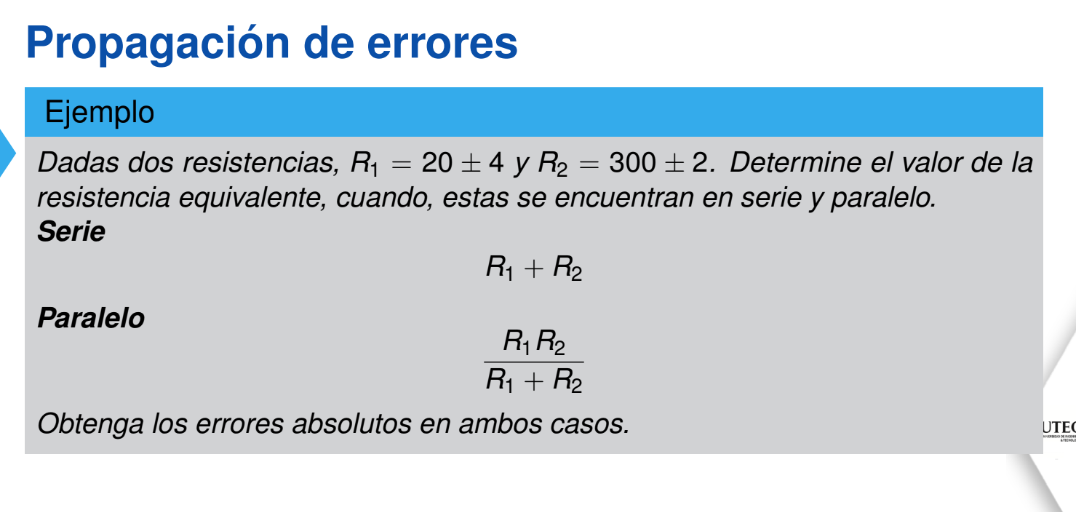

clear all
syms R1 R2

fs = @(R1,R2) R1 + R2;

dfs_dR1 = matlabFunction(diff(fs,R1));
dfs_dR2 = matlabFunction(diff(fs,R2));

R1_val = 20;
R2_val = 300;
eaR1 = 4;
eaR2 = 2;

ea_fs = abs(dfs_dR1()) * eaR1 + abs(dfs_dR2()) * eaR2

ea_fs = 6


fp = @(R1,R2) (R1 * R2)/(R1 + R2);
dfp_dR1 = matlabFunction(diff(fp,R1));
dfp_dR2 = matlabFunction(diff(fp,R2));

ea_fp = abs(dfp_dR1(R1_val,R2_val)) * eaR1 + abs(dfp_dR2(R1_val,R2_val)) * eaR2

ea_fp = 3.5234

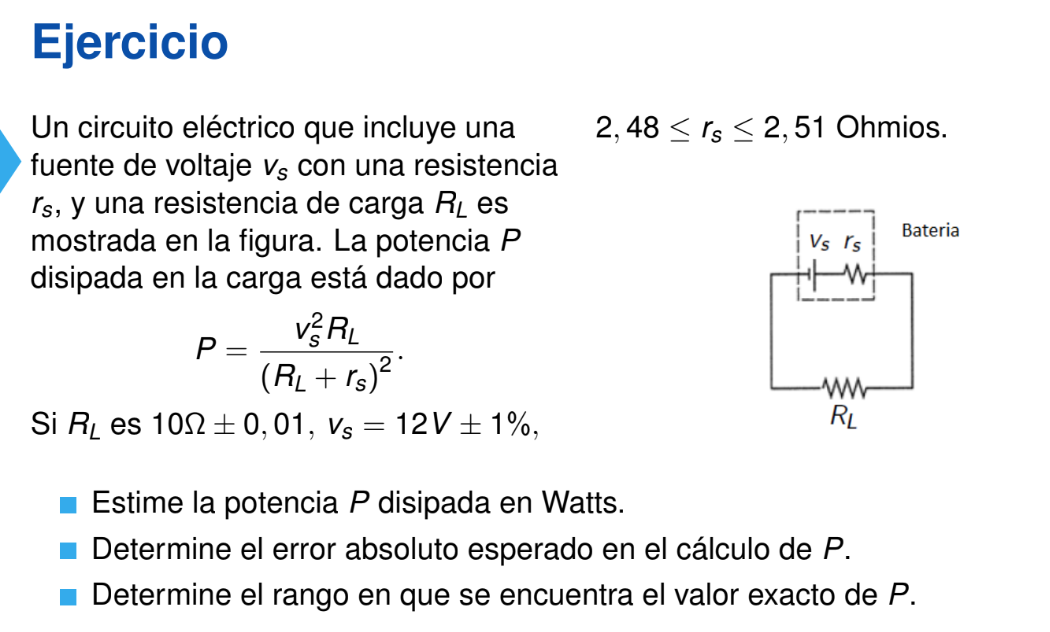

clear all
syms v R r

P = @(R,r,v)(v^2 * R)/(R + r)^2

P = function_handle with value:
    @(R,r,v)(v^2*R)/(R+r)^2



v_val = 12;
R_val = 10;
r_val = (2.48+2.51)/2;

ea_R = 0.01;
ea_v = 1/100 * 12;
ea_r = (2.51-2.48)/2;

dP_dv = matlabFunction(diff(P,v))

dP_dv = function_handle with value:
    @(R,r,v)R.*v.*1.0./(R+r).^2.*2.0


dP_dR = matlabFunction(diff(P,R))

dP_dR = function_handle with value:
    @(R,r,v)v.^2.*1.0./(R+r).^2-R.*v.^2.*1.0./(R+r).^3.*2.0


dP_dr = matlabFunction(diff(P,r))

dP_dr = function_handle with value:
    @(R,r,v)R.*v.^2.*1.0./(R+r).^3.*-2.0



ea_P = abs(dP_dv(R_val,r_val,v_val)) * ea_r + abs(dP_dR(R_val,r_val,v_val)) * ea_R + abs(dP_dr(R_val,r_val,v_val)) * ea_r

ea_P = 0.0507

P_exacto = P(R_val,r_val,v_val)

P_exacto = 9.2234

er_P = ea_P / abs(P_exacto)

er_P = 0.0055

maxP = P_exacto + ea_P

maxP = 9.2741

minP = P_exacto - ea_P

minP = 9.1726